# Comprobación de la distribución de $\xi$

En este script comprobamos numéricamente que la distribución de la variable aleatoria $\xi = \|x_1\|^2 - b^2 \langle x_1, x_i \rangle$ efectivamente converge a una $\mathcal N(\mu, \sigma)$, con $\mu = n/3$ y $\sigma^2 = n (4/45 + b^4/9)$. Esta comprobación se realiza para diferentes combinaciones de valores de $n$ y $b$.

SEED = 12345;
rng(SEED);

M = 10000;
ns = [10, 50, 100, 500, 1000];
bs = [1.5, 1.001];

figure('Position', [0 0 1250 500]);

N = length(ns);
B = length(bs);
index = 1;
for b = bs
    for n = ns
        X = rand(2 * M, n) * 2 - 1;
        x1s = X(1:M, :);
        x2s = X(M+1:2*M, :);
        
        xis = getXis(b, x1s, x2s);
        
        mu = mean(xis);
        sigma = std(xis);
        
        expectedMu = n / 3;
        expectedSigma = sqrt(n * (4 / 45 + b^4 / 9));
        
        x = min(xis):.1:max(xis);
        
        expectedXis = normpdf(x, expectedMu, expectedSigma);
        
        subplot(B, N, index);
        
        h = histogram(xis, 50, 'Normalization', 'pdf');
        hold on
        
        p = plot(x, expectedXis, "LineWidth", 2);
        title(sprintf('n=%d; b=%.3f', n, b), 'FontSize', 14);
        
        fprintf('Expected mean: %.3f', expectedMu);
        fprintf('Found: %.3f', mu);
        
        fprintf('Expected std: %.3f', expectedSigma);
        fprintf('Found: %.3f', sigma);
        
        fprintf("----------------------------------------------");
        
        index = index + 1;
    end
end

Expected mean: 3.333

Found: 3.374

Expected std: 2.552

Found: 2.553

----------------------------------------------

Expected mean: 16.667

Found: 16.708

Expected std: 5.707

Found: 5.719

----------------------------------------------

Expected mean: 33.333

Found: 33.280

Expected std: 8.071

Found: 8.103

----------------------------------------------

Expected mean: 166.667

Found: 166.722

Expected std: 18.047

Found: 18.098

----------------------------------------------

Expected mean: 333.333

Found: 333.576

Expected std: 25.522

Found: 25.252

----------------------------------------------

Expected mean: 3.333

Found: 3.320

Expected std: 1.416

Found: 1.415

----------------------------------------------

Expected mean: 16.667

Found: 16.680

Expected std: 3.166

Found: 3.187

----------------------------------------------

Expected mean: 33.333

Found: 33.336

Expected std: 4.477

Found: 4.519

----------------------------------------------

Expected mean: 166.667

Found: 166.716

Expected std: 10.011

Found: 10.090

----------------------------------------------

Expected mean: 333.333

Found: 333.519

Expected std: 14.158

Found: 14.167

----------------------------------------------

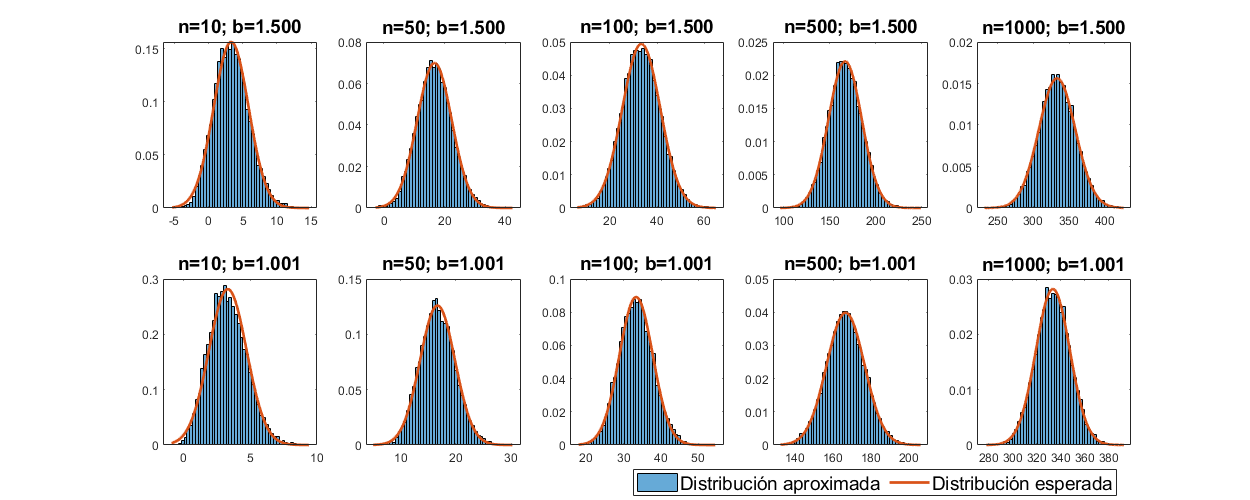


leg = legend([h, p], {'Distribución aproximada', 'Distribución esperada'}, ...
    'Orientation', 'horizontal', 'FontSize', 14);
set(leg, 'Position', [.6 .01 .2 .05], 'Units', 'normalized');

function xis = getXis(b, x1, x2)
    xis = vecnorm(x1, 2, 2).^2 - b^2 * dot(x1, x2, 2);
end